# Calculate volume by LIDAR point cloud

#### *Simple script that calculates volume of terrain object (heap, hill, mountain, etc) by point cloud*

Test data was loaded from [OpenTopography](https://opentopography.org)

Following toolboxes are necessary:

**Lidar Toolbox**

**Computer Vision Toolbox**

### *Load LIDAR data*

clear();
lasReader = lasFileReader(".\lidar_data.laz");
ptCloud = readPointCloud(lasReader);

### *Display point cloud*

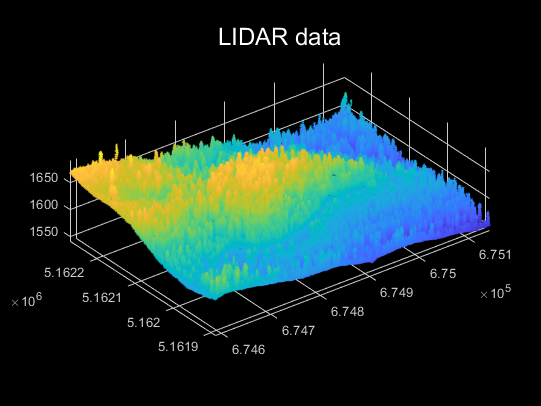

ax = pcshow(ptCloud.Location);
ax.GridAlphaMode = "manual";
ax.GridAlpha = 1;
title('LIDAR data', 'FontWeight','Normal','FontSize',18,'Color','white');

### *Do filtering*

% With pcdenoise(...)

### *Convert point cloud to surface*

dens = 27800;
x = double(ptCloud.Location((1:dens:end),1));
y = double(ptCloud.Location((1:dens:end),2));
z = double(ptCloud.Location((1:dens:end),3));

sx = double(sum(size(x)));
sy = double(sum(size(y)));

xg = linspace(min(x), max(x), sx);
yg = linspace(min(y), max(y), sy);

[Xg, Yg] = meshgrid(xg, yg);
Zg = griddata(x, y, z, Xg, Yg);

Zg(isnan(Zg))=min(min(Zg));


### *Calculate volume*

vol = trapz(xg,trapz(yg, Zg));

### *Display surface*

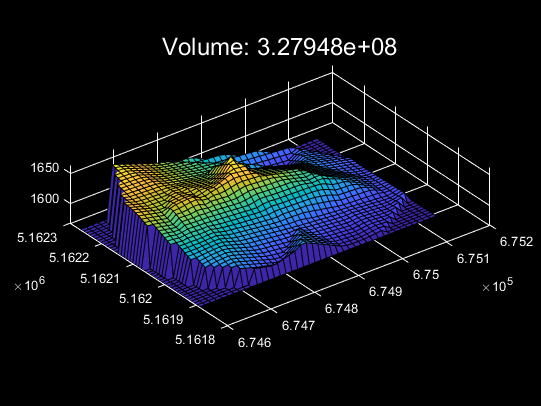


figure(Color='black');
s = surf(Xg, Yg, Zg);
s.Parent.Color = "black";
s.Parent.XColor = 'white';
s.Parent.YColor = 'white';
s.Parent.ZColor = 'white';

s.Parent.GridAlphaMode = "manual";
s.Parent.GridAlpha = 1;

pbaspect(daspect());

header = sprintf('Volume: %0.5e', vol);
title(header, 'FontWeight','Normal','FontSize',18,'Color','white');

lighting gouraud
shading  faceted